# Asteroid Optical Navigation

ASEN 5044 Final Project Description

*Group Members: *James Monaco, AJ Cuddeback, Grant Kirchoff

## Part 1: Deterministic System Analysis

### 1. Nonlinear Simulation

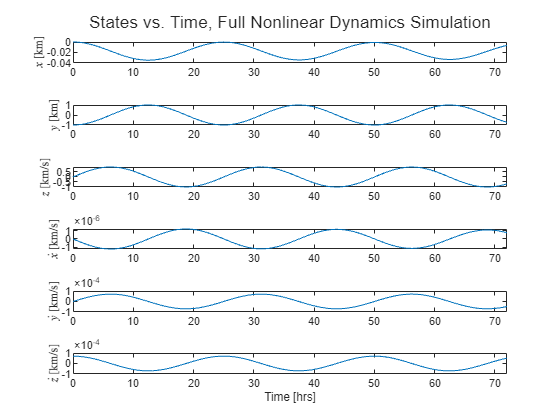

% bringing in simulation data and provided data
run('sim_setup.m')
load orbitdetermination-finalproj_data_2023_11_14.mat

% solar radiation pressure 
a_SRP = -Phi_0 / norm(r_S)^2 * (1 + 4/9 * rho) * A_M * r_S / norm(r_S);

% non-linear simualtion
x_0 = [r_nom; dr_nom];
options = odeset('RelTol',1e-12);
t_obs = unique(y_table(:, 1));  % [s]
[t_ode45,x_ode45] = ode45(@(t_in,x_in) orbit(t_in,x_in,a_SRP,mu_A), t_obs, x_0, options);
[steps,n] = size(x_ode45);

% plotting non-linear simulation solution
figure;
fig = tiledlayout(n,1);
ylabels = ["$x$ [km]", "$y$ [km]","$z$ [km/s]","$\dot x$ [km/s]", "$\dot y$ [km/s]","$\dot z$ [km/s]"];
for i = 1:n
    nexttile(fig)
    plot(t_ode45/60/60,x_ode45(:,i))
    xlim([t_obs(1)/60/60, t_obs(end)/60/60])
    ylabel(ylabels(i),Interpreter='latex')
end
xlabel("Time [hrs]")
title(fig,"States vs. Time, Full Nonlinear Dynamics Simulation")

### **2. Measurement Model**

% setting things nup
r = x_ode45(:, 1:3)';               % xyz coords of satellite
[~,num_lmks] = size(pos_lmks_A);
u_obs = zeros(num_lmks,steps);
v_obs = zeros(num_lmks,steps);
for i = 1:num_lmks                  % perform observations for each landmark...
    l = pos_lmks_A(:,i);
    utot = zeros(1, steps);
    vtot = zeros(1, steps);
    for jj=1:steps                  % ... at each time step
        RNC = R_CtoN(:, :, jj);
        % w_A is stupid, and is a periodicity [sec/rot]
        % 1/period * sec is number of rotations
        % rotations * 2 * pi is radians 
        th = 2* pi * 1/w_A * t_obs(jj);  % [deg]
        R_NA = [cos(th) -sin(th) 0; 
                sin(th) cos(th)  0; 
                0       0        1];
        [u, v] = measure(l, r(:, jj), RNC, u_0, v_0, f, R_NA);
        utot(1, jj) = u;
        vtot(1, jj) = v;
    end
    u_obs(i,:) = utot;
    v_obs(i,:) = vtot;
end

% plotting observations
figure
fig = tiledlayout(2,1);
mkrs = ["o","+","*",".","x","square","diamond","v","^",">"]

mkrs = 1×10 string array
    "o"    "+"    "*"    "."    "x"    "square"    "diamond"    "v"    "^"    ">"


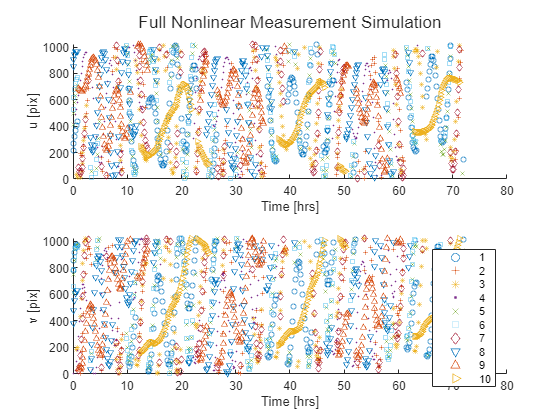

sz = 15; 

% plotting u data
nexttile(fig)
hold on 
for i = 1:10
    s = scatter(t_obs/60/60,u_obs(i,:),mkrs(i));
    s.SizeData = sz;
end
hold off
xlabel('Time [hrs]')
ylabel('u [pix]')

% plotting v data
nexttile(fig)
hold on 
for i = 1:10
    s = scatter(t_obs/60/60,v_obs(i,:),mkrs(i));
    s.SizeData = sz;
end
hold off

% formatting
xlabel('Time [hrs]')
ylabel('v [pix]')
legend(string(1:10))
title(fig,"Full Nonlinear Measurement Simulation")

### 2. CT Jacobians

Solved by hand. Testing out to see if I know how to use git.

% dF/dx matrix, evaluated at the nominal point
dFdx_nom =[ 0   0   0   1   0   0;
            0   0   0   0   1   0;
            0   0   0   0   0   1;
            dfdx_ij(r_nom,1,mu_A)   0   0   0   0   0;
            0   dfdx_ij(r_nom,2,mu_A)   0   0   0   0;
            0   0   dfdx_ij(r_nom,3,mu_A)   0   0   0];
% for notational convenience
m = 3; % 1 unput
A = dFdx_nom;
B = zeros(n,m);
B(4:end,:) = eye(3);

### 3. DT Linarized Model

% bringing into discrete time
F_check = expm(A*dt_obs);
A_hat = zeros(n+m,n+m);
A_hat(1:n,1:n) = A;
A_hat(1:n,(n+1):end) = B;
exmp_A_hat = expm(A_hat*dt_obs);
F = exmp_A_hat(1:n,1:n);
G = exmp_A_hat(1:n,(n+1):end);

### 4. Simlation of DT linearized Model

No process noise, no measurement nose, no control input perturbations

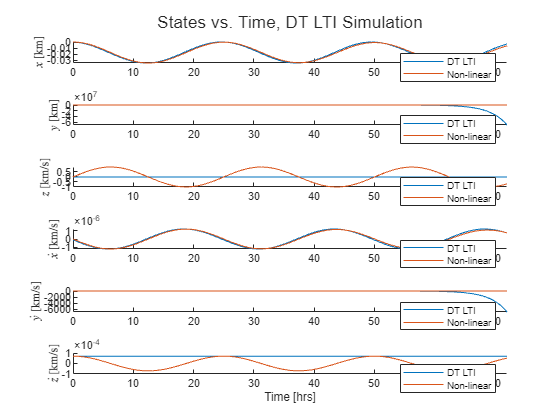

% performing the simulation
dx_DT = zeros(steps,n); 
dx_DT(1,:) = [1e-5,1e-5,1e-5,1e-7,1e-7,1e-7];
for k = 1:steps-1
    dx_k = F*dx_DT(k,:)' + G*a_SRP;
    dx_DT(k+1,:) = dx_k';
end
x_DT = dx_DT + [r_nom', dr_nom'];

% plotting linear simulation solution
figure;
fig = tiledlayout(n,1);
ylabels = ["$x$ [km]", "$y$ [km]","$z$ [km/s]","$\dot x$ [km/s]", "$\dot y$ [km/s]","$\dot z$ [km/s]"];
for i = 1:n
    nexttile(fig)
    hold on
    plot(t_ode45/60/60,x_DT(:,i))
    % plot(t_ode45/60/60,x_ode45(:,i))
    hold off
    % xlim([t_obs(1)/60/60, t_obs(end)/60/60])
    xlim([t_obs(1)/60/60, 72])
    ylabel(ylabels(i),Interpreter='latex')
    legend('DT LTI','Non-linear')
end
xlabel("Time [hrs]")
title(fig,"States vs. Time, DT LTI Simulation")

Validating against full nonlinear simulation: 

Plotting results: 

## Part 2: Stochastic Nonlienar Filtering

### 5. Linarized KF 

- Use specified nominal state trajectory, control inputs, and covariance matrix

-  Use NEES and NIS $\chi^2
$ test based on MC TMT simulations to tune and validate LKF

### 6. Extended KF 

### 7. Implement LKF and EKF for Estimation

function dx = orbit(~,x_in,a_SRP,mu_A)
    % calculating pertibation forces
    r = x_in(1:3);
    f = a_SRP + a_2B(r,mu_A);
    
    % building the derivative vector
    dx = zeros(size(x_in));
    dx(1:3) = x_in(4:6);
    dx(4:6) = f;
end

function f = a_2B(r,mu_A)
    % calculating gravitational forces
    f = -mu_A / norm(r)^3 * r;
end 

function [u, v] = measure(l, r, RNC, u0, v0, f, R_NA)
    % calculate pixel coordinate of SC
    
    % unit vectors of camera coordinate system
    ihat = RNC(:, 1);
    jhat = RNC(:, 2);
    khat = RNC(:, 3);

    % transformed coords based on asteriod rotation
    % the coords of the satellite are in the inertial frame, and do NOT
    % require transformation 
    l = R_NA * l;
    
    % if the asteriod occuludes the object, return with no observations
    if l'*khat > 0
        u = NaN;
        v = NaN;
        return
    end
    
    % calculating coordinates of observation 
    u = f * ((l-r)'*ihat)/((l-r)'*khat) + u0;
    v = f * ((l-r)'*jhat)/((l-r)'*khat) + v0;

    % making sure object is within FOV
    if u<0 || u>1024 || v<0 || v>1024 || (l-r)'*khat < 0
        u = NaN;
        v = NaN;
    end
end

function dfdx_ij = dfdx_ij(r,i,mu_A)
    dfdx_ij  = mu_A * (3*r(i)^2/(norm(r)^5) - 1/(norm(r)^3));
end